%1
a= 1 + mod(119,3)

a = 3

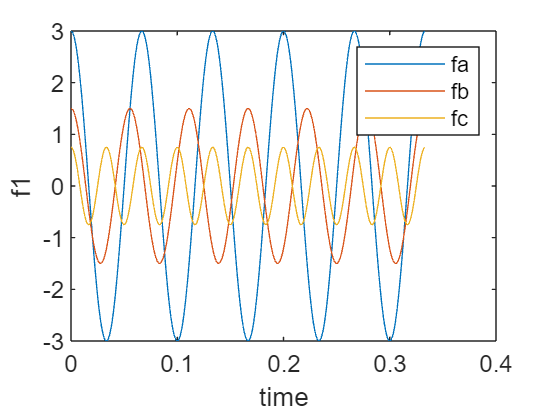

t= [0:0.001:1/a];
fa= inline('a*cos(5*a*2*pi*t)','a','t');
fb= inline('a/2*cos(6*a*2*pi*t)','a','t');
fc= inline('a/4*cos(10*a*2*pi*t)','a','t');

plot(t,fa(a,t))
hold on
plot(t,fb(a,t))

plot(t,fc(a,t))
xlabel("time")
ylabel("f1")
legend("fa","fb","fc")
hold off

f2 = fa(a,t)+fb(a,t)+fc(a,t);
plot(t,f2)
xlabel("time")
ylabel("f2")
legend("f2")

%3a
fs=14*a;
T=1/fs;
t = [0:T:1/a];
f2 = fa(a,t)+fb(a,t)+fc(a,t);
subplot(3,1,1)
stem(t,f2)
xlabel('time')
ylabel("f3a")
legend("f= 14a")


%3b
fs=20*a;
T=1/fs;
t = [0:T:1/a];
f2 = fa(a,t)+fb(a,t)+fc(a,t);
subplot(3,1,2)
stem(t,f2)
xlabel('time')
ylabel("f3b")
legend("f= Nyquist rate")

%3c
fs=9*a;
T=1/fs;
t = [0:T:1/a];
f2 = fa(a,t)+fb(a,t)+fc(a,t);
subplot(3,1,3)
stem(t,f2)
xlabel('time')
ylabel("f3c")
legend("f= 20a")

%4

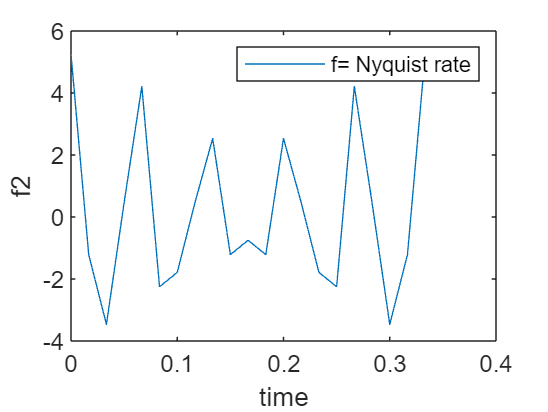

%4
figure;
fs=14*a;
T=1/fs;
t = [0:T:1/a];
f2 = fa(a,t)+fb(a,t)+fc(a,t);
plot(t,f2)
xlabel("time")
ylabel("f2")
legend("f = 14a")

fs=20*a;
T=1/fs;
t = [0:T:1/a];
f2 = fa(a,t)+fb(a,t)+fc(a,t);
plot(t,f2)
xlabel("time")
ylabel("f2")
legend("f= Nyquist rate")

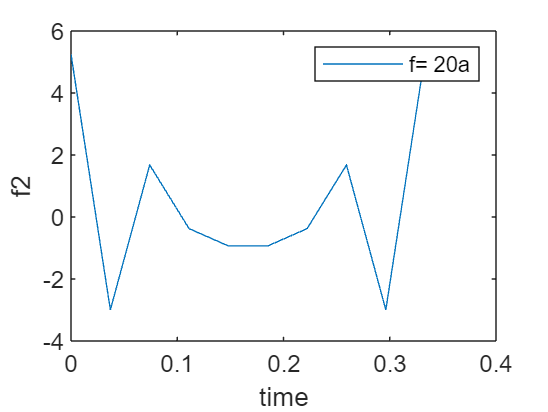


fs=9*a;
T=1/fs;
t = [0:T:1/a];
f2 = fa(a,t)+fb(a,t)+fc(a,t);
plot(t,f2)
xlabel("time")
ylabel("f2")
legend("f= 20a")

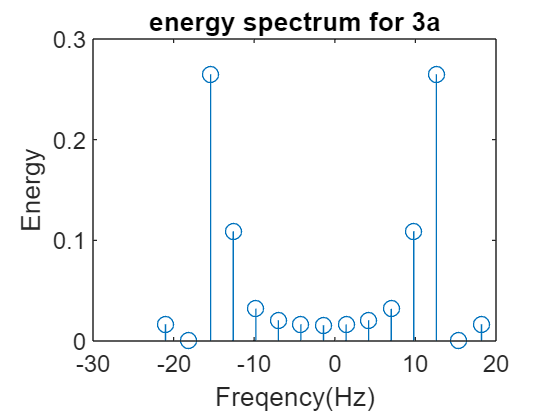

%5
fs=14*a;
T=1/fs;
t = [0:T:1/a];
f2 = fa(a,t)+fb(a,t)+fc(a,t);
N= length(f2);
Y= fft(f2,N);
k=fftshift(Y);
ff= [0:1:N-1]*fs/N-fs/2;
energy = ((abs(k)/fs).^2);
figure;
stem(ff,energy)
title("energy spectrum for 3a")
xlabel("Freqency(Hz)")
ylabel("Energy")

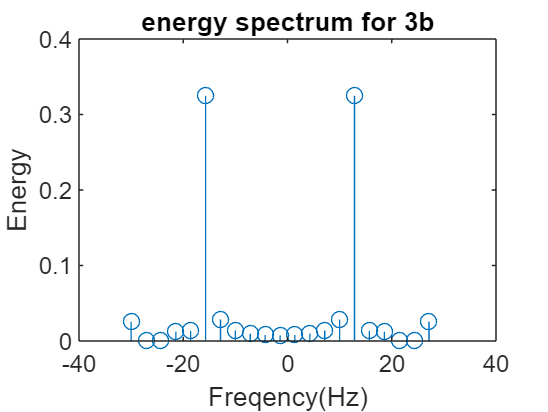



fs=20*a;
T=1/fs;
t = [0:T:1/a];
f2 = fa(a,t)+fb(a,t)+fc(a,t);
N= length(f2);
Y= fft(f2,N);
k=fftshift(Y);
ff= [0:1:N-1]*fs/N-fs/2;
energy = ((abs(k)/fs).^2);
figure;
stem(ff,energy)
title("energy spectrum for 3b")
xlabel("Freqency(Hz)")
ylabel("Energy")

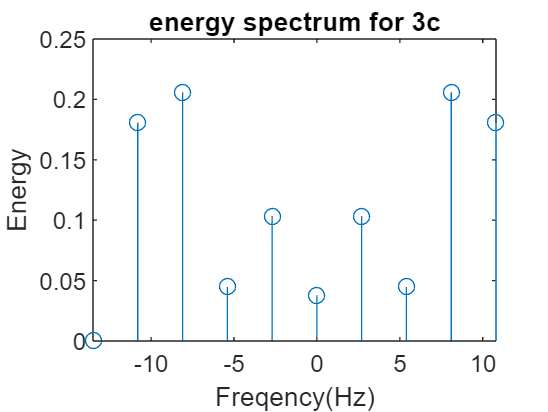



fs=9*a;
T=1/fs;
t = [0:T:1/a];
f2 = fa(a,t)+fb(a,t)+fc(a,t);
N= length(f2);
Y= fft(f2,N);
k=fftshift(Y);
ff= [0:1:N-1]*fs/N-fs/2;
energy = ((abs(k)/fs).^2);
figure;
stem(ff,energy)
title("energy spectrum for 3c")
xlabel("Freqency(Hz)")
ylabel("Energy")

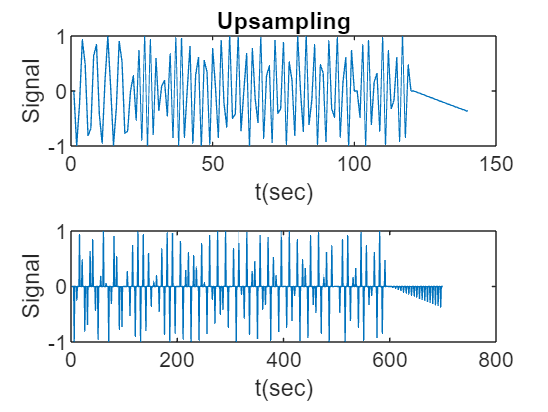

% Upsampling
Fs = 20;
t = linspace(0,1,Fs);
Do = sin(2*pi*261.63*t);
Re = sin(2*pi*293.66*t);
Mi = sin(2*pi*329.63*t);
Fa = sin(2*pi*349.23*t);
So = sin(2*pi*392.00*t);
La = sin(2*pi*220.00*t);
Ti = sin(2*pi*246.94*t);
z = [Do,Re,Mi,Fa,So,La,Ti];
figure;
subplot(2,1,1)
plot(z)
ylabel('Signal');
xlabel('t(sec)');
title('Upsampling')

y1 = upsample(z,5);
subplot(2,1,2)
plot(y1)
ylabel('Signal');
xlabel('t(sec)');

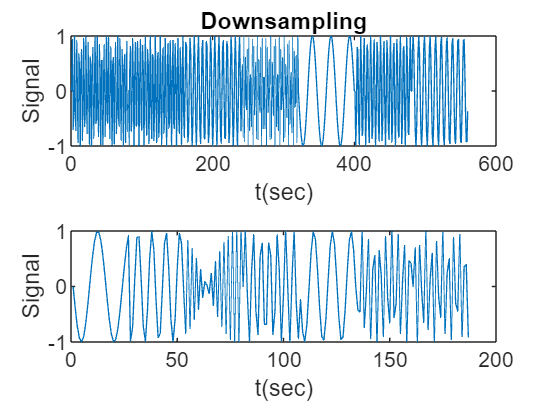


% Downsampling
Fs = 80;
t = linspace(0,1,Fs);
Do = sin(2*pi*261.63*t);
Re = sin(2*pi*293.66*t);
Mi = sin(2*pi*329.63*t);
Fa = sin(2*pi*349.23*t);
So = sin(2*pi*392.00*t);
La = sin(2*pi*220.00*t);
Ti = sin(2*pi*246.94*t);
z = [Do,Re,Mi,Fa,So,La,Ti];
figure;
subplot(2,1,1)
plot(z);
ylabel('Signal');
xlabel('t(sec)');
title('Downsampling')

y2 = downsample(z,3);
subplot(2,1,2)
plot(y2);
ylabel('Signal');
xlabel('t(sec)');


% For audio 
Fs = 44100;
t = linspace(0,5,20000);
Do = sin(2*pi*261.63*t);
Re = sin(2*pi*293.66*t);
Mi = sin(2*pi*329.63*t);
Fa = sin(2*pi*349.23*t);
So = sin(2*pi*392.00*t);
La = sin(2*pi*220.00*t);
Ti = sin(2*pi*246.94*t);
z = [Do,Re,Mi,Fa,So,La,Ti];
audiowrite('ad2.wav',z,Fs);
%sound(z,44100);
%sound(z,22050);
%sound(z,10250);



[s,Fs] =audioread('ad2.wav');
y1 = downsample(s,2);
y2 = upsample(s,3);
%sound(y1,Fs)